## PROJECT 1

### Miscellaneous

Adding the path to the `functions `and `data` folder. In `functions `you can find the functions used in this project. In `data` you can find the datasets used.

addpath('./functions');
addpath('./data');

Created a function `load_data `that takes as input the location of the CIFAR10 dataset. The function looks for the "cifar-10-batches-mat" folder and creates a training and test set. Additionally, the function carries out the some permutation on the data such as: reshape, converts labels to categorical, flips the images by 90deg.

[XTrain, YTrain, XTest, YTest] = load_data('data');

This code samples randomly from the training set and displays the image with its label.

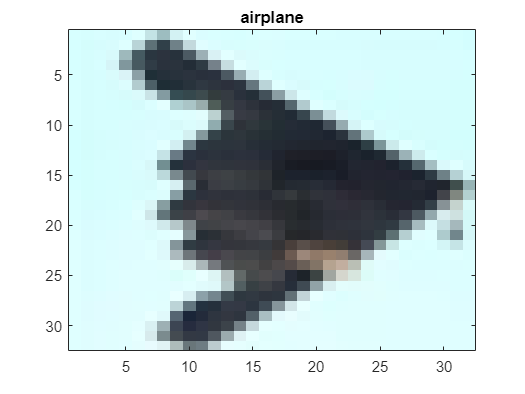

idx = randi(size(XTrain,4));

imagesc(XTrain(:,:,:,idx))
title(YTrain(idx))

### Base Model

Here I defined a first basic classifier and perfomed its training.

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       13.28% |       2.3054 |          0.0010 |
|       1 |          50 |       00:00:13 |       10.16% |       2.3038 |          0.0010 |
|       1 |         100 |       00:00:22 |       21.09% |       2.1012 |          0.0010 |
|       1 |         150 |       00:00:29 |       27.34% |       2.0246 |          0.0010 |
|       1 |         200 |       00:00:35 |       28.91% |       1.9084 |          0.0010 |
|       1 |         250 |       00:00:44 |       31.25% |       1.7814 |          0.0010 |
|       1 |         300 |       00:00:52 |       31

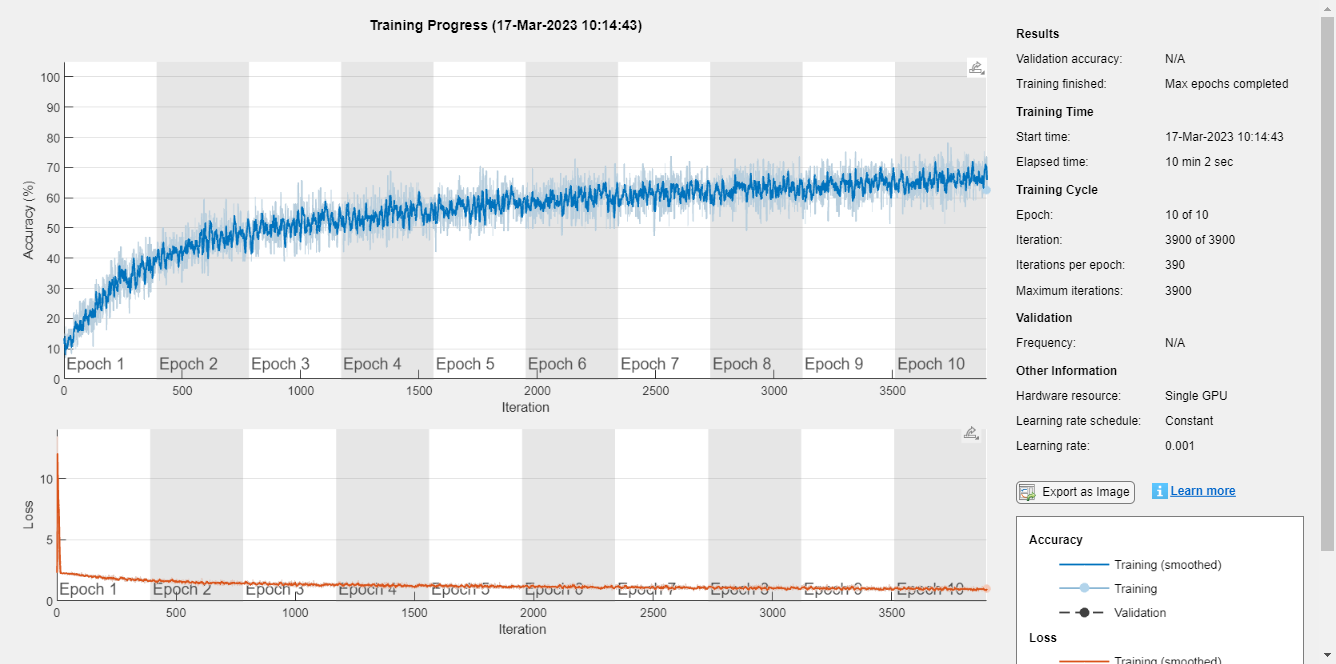

layers = basic_cnn_classifier_v2();

opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');

basic_net = trainNetwork(XTrain, YTrain, layers, opts);

preds = basic_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 60.92%


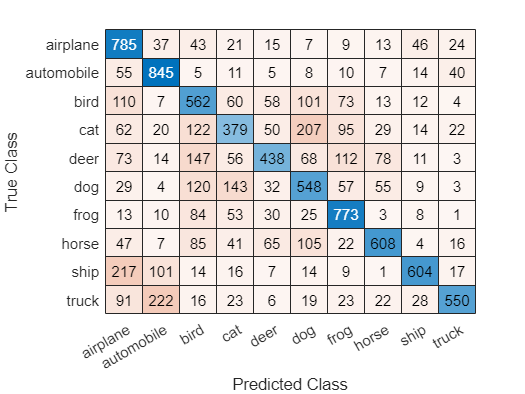

confusionchart(YTest,preds)

### Improved Model

Here I improved the model and trained it.

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |        6.25% |       10.94% |       2.3035 |       2.3017 |          0.0002 |
|       1 |          50 |       00:00:18 |       21.09% |       21.94% |       2.2050 |       2.2018 |          0.0002 |
|       1 |         100 |       00:00:30 |       21.09% |       24.34% |       2.1074 |       2.0737 |          0.0002 |
|       1 |         150 |       00:00:39 |       31.25% |       29.06% |       1.9105 |       1.9642 |          0.

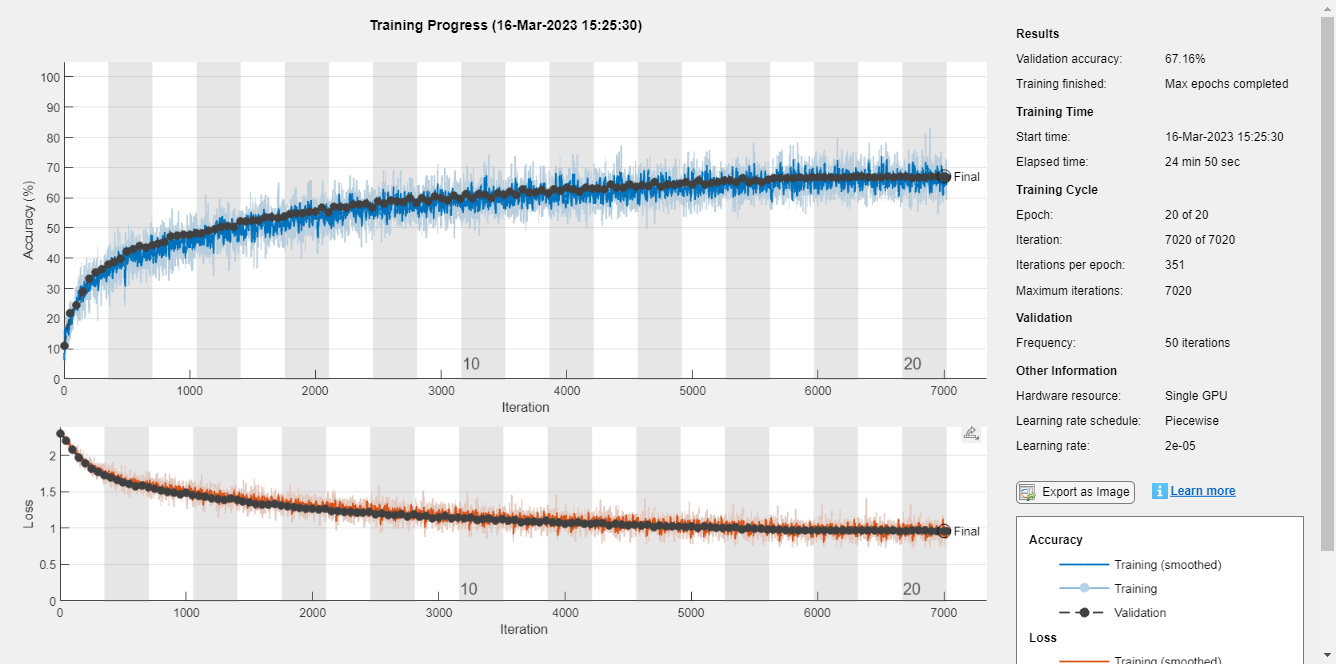

layers = improved_cnn_classifier_v2();
[X_train, X_val, Y_train, Y_val] = train_test_split(XTrain,YTrain,0.1);
opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 16, ...
    'L2Regularization', 0.004, ...
    'ValidationData',{X_val, Y_val}, ...
    'OutputNetwork','best-validation-loss', ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');

improved_net = trainNetwork(X_train, Y_train, layers, opts);

preds = improved_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 66.6%


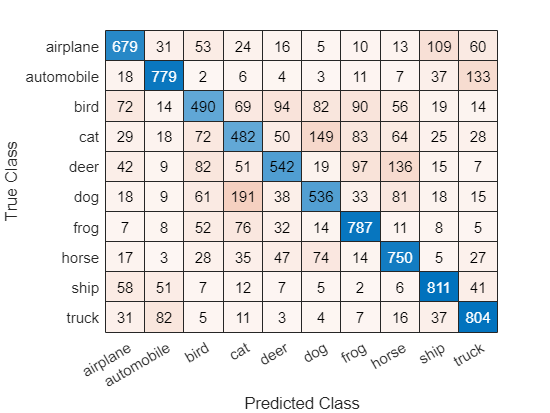

confusionchart(YTest,preds)

### Ablation Study

#### Improved Model (no scheduler)

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       10.16% |        9.88% |       2.3029 |       2.2995 |          0.0002 |
|       1 |          50 |       00:00:04 |       15.62% |       15.64% |       2.2066 |       2.1967 |          0.0002 |
|       1 |         100 |       00:00:07 |       18.75% |       21.54% |       2.1512 |       2.1287 |          0.0002 |
|       1 |         150 |       00:00:09 |       22.66% |       23.72% |       2.0048 |       2.0665 |          0.

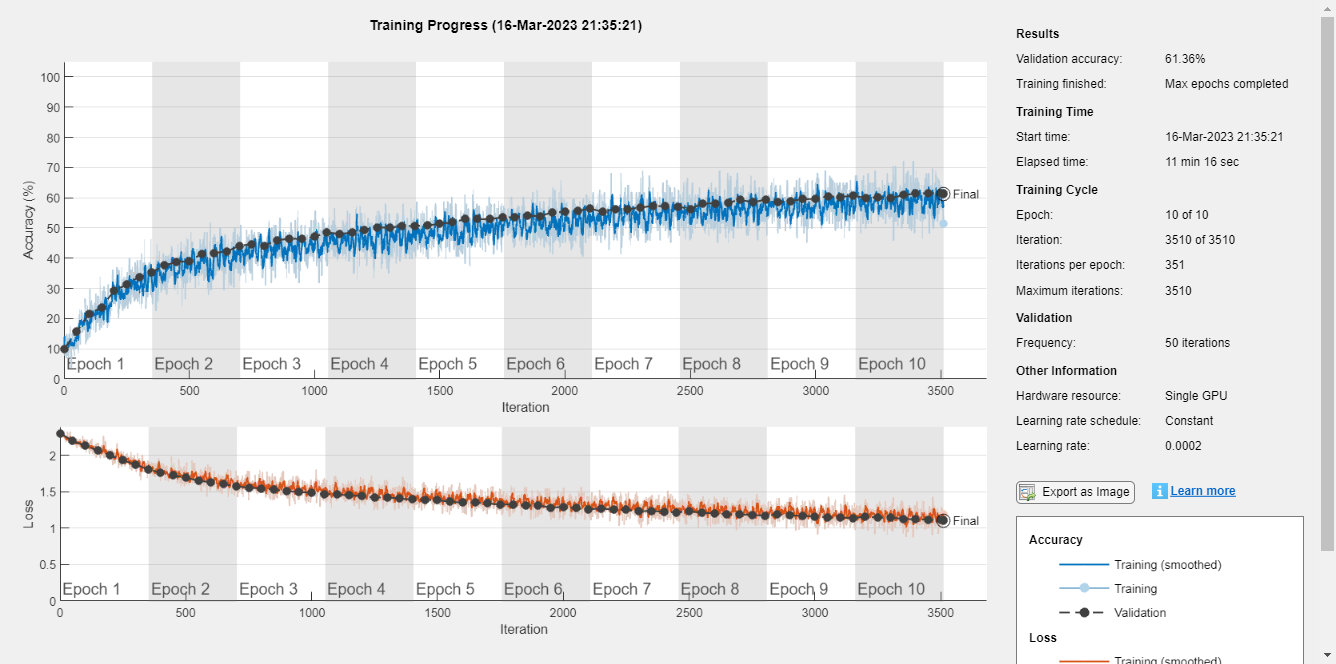

layers = improved_cnn_classifier_v2();
[X_train, X_val, Y_train, Y_val] = train_test_split(XTrain,YTrain,0.1);
opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 16, ...
    'L2Regularization', 0.004, ...
    'ValidationData',{X_val, Y_val}, ...
    'OutputNetwork','best-validation-loss', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');

improved_net = trainNetwork(X_train, Y_train, layers, opts);

preds = improved_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 60.51%


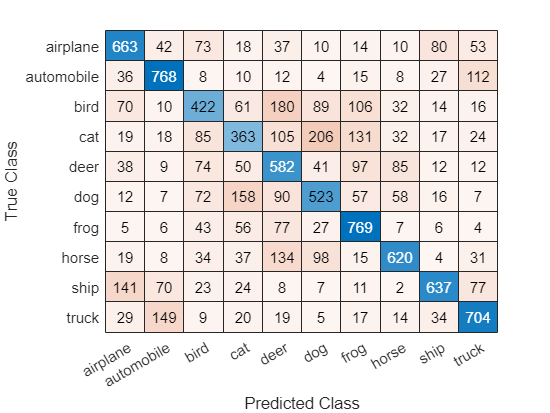

confusionchart(YTest,preds)

#### Improved Model (no learn drop factor)

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        5.47% |        9.30% |       2.3046 |       2.3010 |          0.0002 |
|       1 |          50 |       00:00:04 |       11.72% |       11.68% |       2.2648 |       2.2652 |          0.0002 |
|       1 |         100 |       00:00:06 |       15.62% |       19.70% |       2.1902 |       2.2086 |          0.0002 |
|       1 |         150 |       00:00:08 |       21.88% |       26.88% |       2.1346 |       2.1125 |          0.

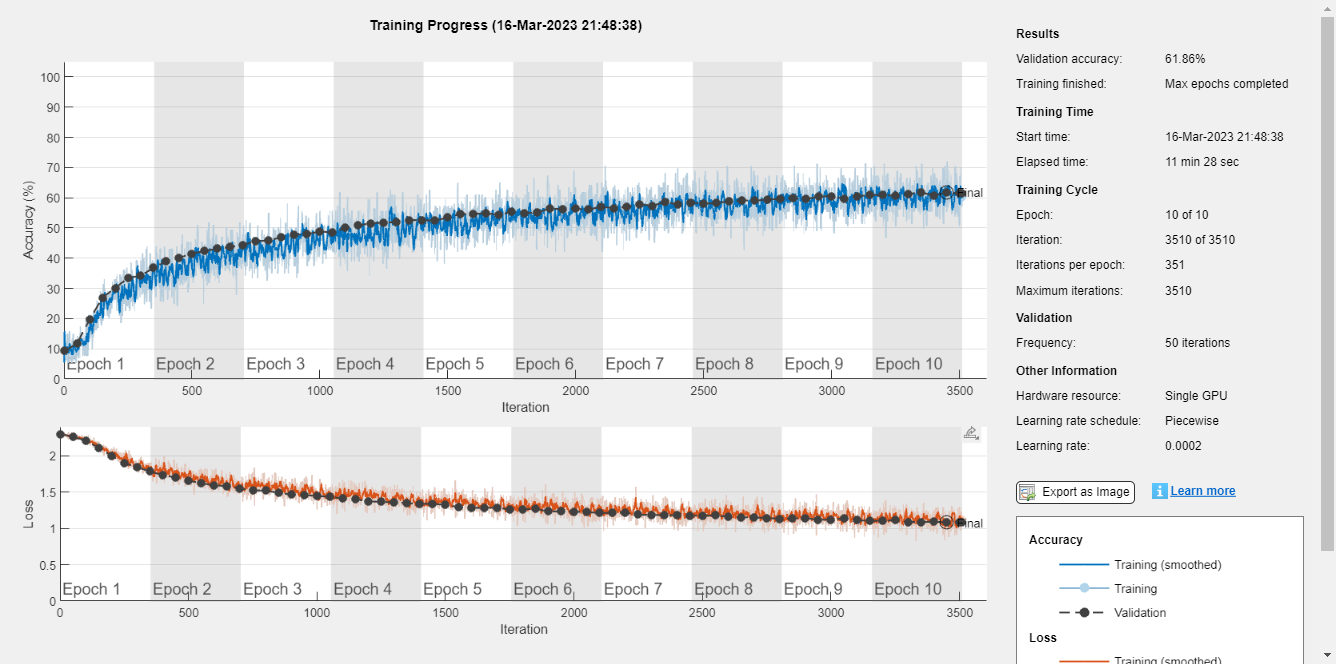

layers = improved_cnn_classifier_v2();
[X_train, X_val, Y_train, Y_val] = train_test_split(XTrain,YTrain,0.1);
opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateSchedule', 'piecewise', ...
    'L2Regularization', 0.004, ...
    'ValidationData',{X_val, Y_val}, ...
    'OutputNetwork','best-validation-loss', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');

improved_net = trainNetwork(X_train, Y_train, layers, opts);

preds = improved_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 62.1%


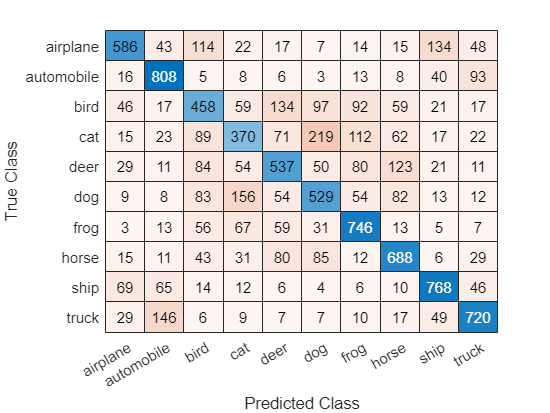

confusionchart(YTest,preds)

#### Improved Model (no l2 regularization)

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        7.81% |        9.58% |       2.3030 |       2.3009 |          0.0002 |
|       1 |          50 |       00:00:16 |       21.88% |       18.68% |       2.1780 |       2.1987 |          0.0002 |
|       1 |         100 |       00:00:29 |       21.88% |       24.12% |       2.0851 |       2.0689 |          0.0002 |
|       1 |         150 |       00:00:41 |       32.03% |       26.98% |       1.9193 |       1.9670 |          0.

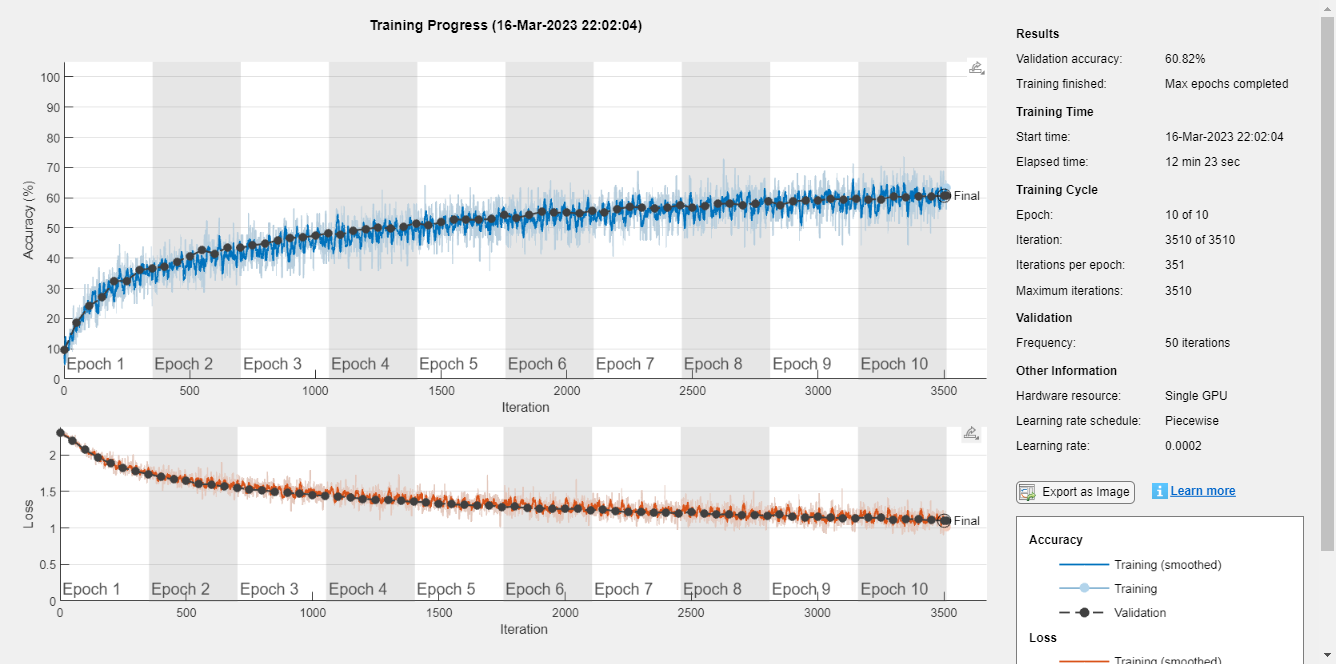

layers = improved_cnn_classifier_v2();
[X_train, X_val, Y_train, Y_val] = train_test_split(XTrain,YTrain,0.1);
opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 16, ...
    'ValidationData',{X_val, Y_val}, ...
    'OutputNetwork','best-validation-loss', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');

improved_net = trainNetwork(X_train, Y_train, layers, opts);

preds = improved_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 61.55%


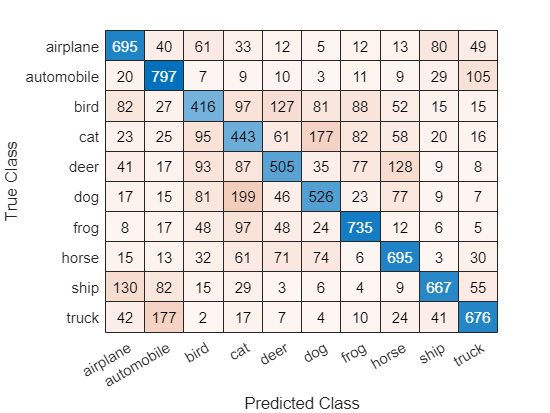

confusionchart(YTest,preds)

#### Improved Model (no batch norm)

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        6.25% |       11.16% |       2.3075 |       2.3557 |          0.0002 |
|       1 |          50 |       00:00:04 |       18.75% |       20.14% |       2.2579 |       2.1762 |          0.0002 |
|       1 |         100 |       00:00:06 |       14.84% |       23.94% |       2.1735 |       2.0796 |          0.0002 |
|       1 |         150 |       00:00:08 |       19.53% |       30.46% |       2.0732 |       1.9230 |          0.

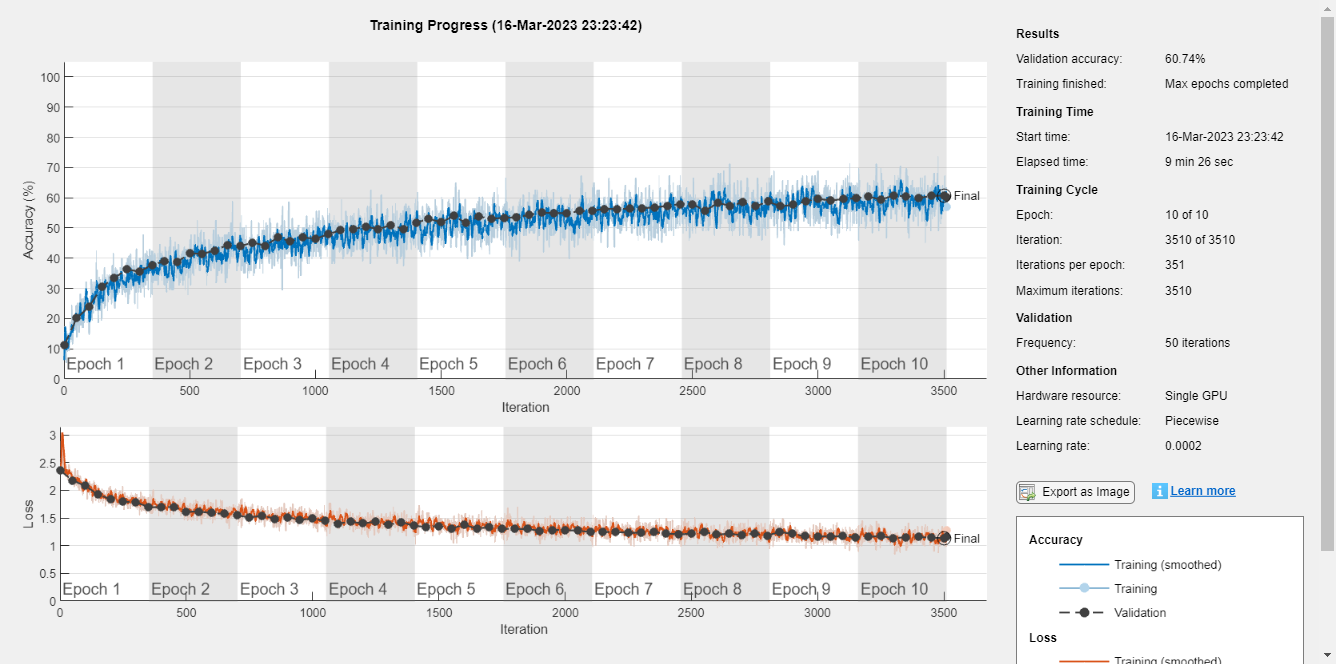

layers = improved_cnn_classifier_v2();
[X_train, X_val, Y_train, Y_val] = train_test_split(XTrain,YTrain,0.1);
opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 16, ...
    'L2Regularization', 0.004, ...
    'ValidationData',{X_val, Y_val}, ...
    'OutputNetwork','best-validation-loss', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');

improved_net = trainNetwork(X_train, Y_train, layers, opts);

preds = improved_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 60.65%


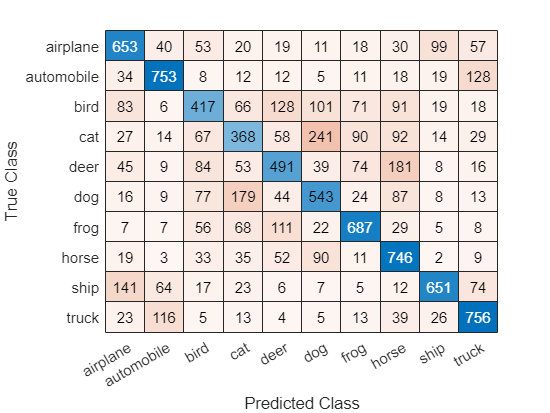

confusionchart(YTest,preds)

#### Improved Model (no drop out)

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        3.91% |       14.02% |       2.3033 |       2.3016 |          0.0002 |
|       1 |          50 |       00:00:05 |       21.09% |       18.82% |       2.2298 |       2.2252 |          0.0002 |
|       1 |         100 |       00:00:07 |       27.34% |       25.58% |       2.1076 |       2.1120 |          0.0002 |
|       1 |         150 |       00:00:09 |       26.56% |       29.04% |       2.0331 |       2.0245 |          0.

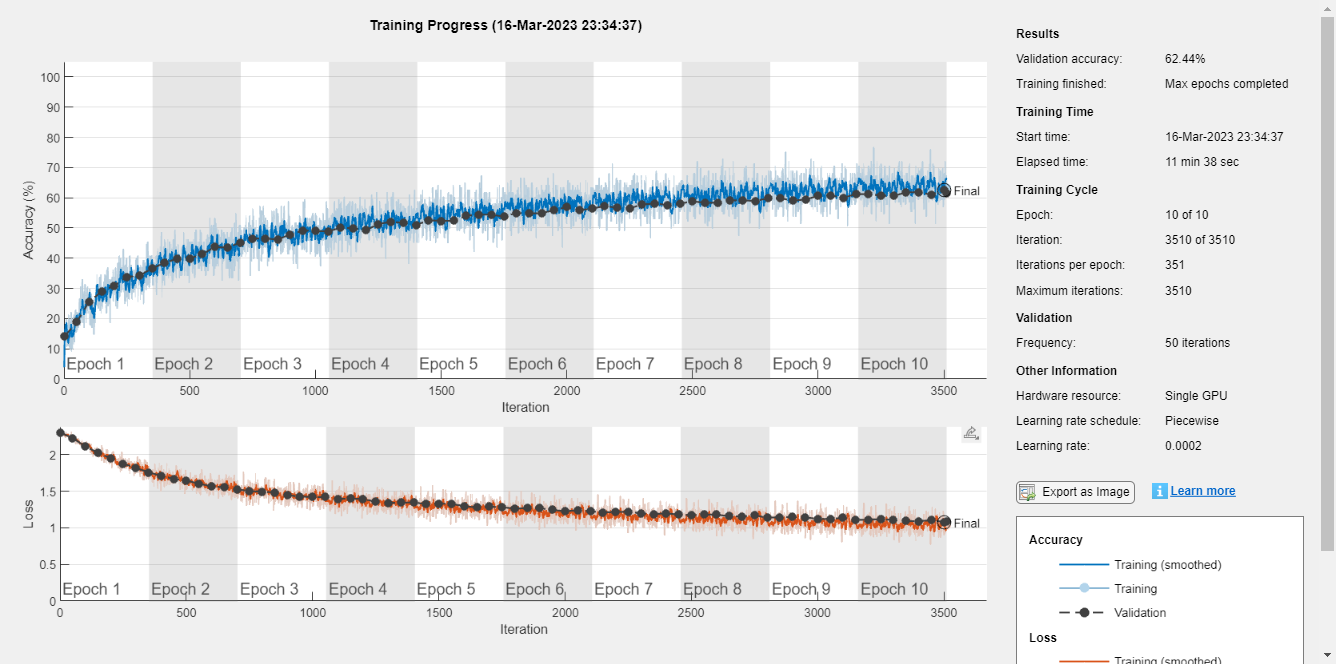

layers = improved_cnn_classifier_v2();
[X_train, X_val, Y_train, Y_val] = train_test_split(XTrain,YTrain,0.1);
opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 16, ...
    'L2Regularization', 0.004, ...
    'ValidationData',{X_val, Y_val}, ...
    'OutputNetwork','best-validation-loss', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');

improved_net = trainNetwork(X_train, Y_train, layers, opts);

preds = improved_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 62.48%


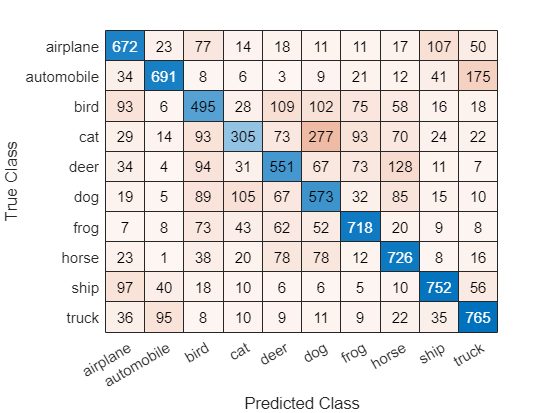

confusionchart(YTest,preds)